# **Controller Tuning **

**Combined Braking or Accelerating **

## for

# `longitudinal Vehicle Motion Control from gain scheduled LTI systems modeled on more complex dynamics.`

`Simulink & Matlab`

`Brian Lesko, Graduate Researcher and Teaching Associate, Masters of mechanical engineering student `

`8/21/23`

` Ohio State University`

`with use of Robust Controls of Mechatronic Systems by Dr. Levent Guvenc`

clc; clear; close all;

% Controller and vehicle Plant Info
load('longitudinalModelData80923.mat')
LMD = longitudinalModelData80823

LMD = 107×11 table
     Vs     Tm_Tb       K          T          rmse       time     avg_acc       dX        Ve      Tm     Tb
    ____    _____    ________    ______    __________    ____    _________    ______    ______    ___    __

       0       0      0.52277    198.47      0.013211      0             0         0         0      0    0 
    0.01      55      0.53809    111.13      0.010918    600      0.049325     14695    29.605     55    0 
    0.01      80      0.48331    85.937     0.0091168    600      0.064442     20125    38.675     80    0 
    0.01     105      0.43781    71.785     0.0078491    600      

load('accControllersData81623.mat')
accC = accControllersData81623;
load('brakeControllersData81623.mat')
brakeC = brakeControllersData81623;
controllers = [accC;brakeC]

controllers = 10×6 table
     Vs     Tm_Tb    Kp      Ki       Kd       N   
    ____    _____    ___    _____    ____    ______

    0.01     170     4.5    0.111    14.7    0.0646
      44     170      10      0.3    3.75    0.0575
      44      40     -10    -0.15     -40      0.04
    0.01      40      12     0.15      60      0.04
      22      40       7    0.125       1      0.07
      22     170      15      0.3       1      0.07
     5.1      -6       1     0.05       8      0.06
     5.1    -290      90       17      15       0.1
    44.9      -6     0.7    0.007    0.55      0.03
    44.9    -290      20      0.8       2       0.1


# consecutive 1 mps step inputs, 

# 70% of result -> 70% result -> ...

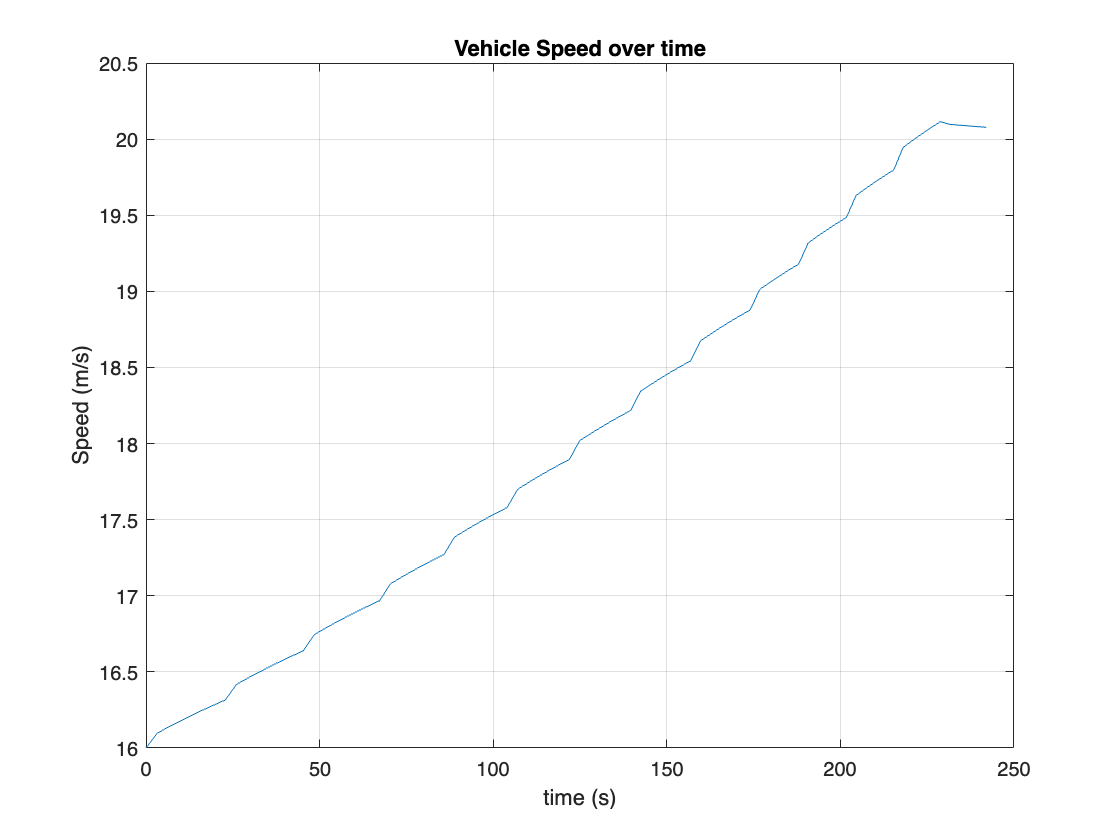

vstart = 16;
torque = 60;
Ref = 20;

stepAmp = 1;
fraction = .3;

achievedStep = stepAmp*fraction;

% # of 1 m/s increases to get from vstart to Ref Velocity
nFullSteps = floor((Ref - vstart)/(stepAmp*fraction));
remainder = mod(Ref - vstart,(stepAmp*fraction)); 

%initialize vars
vNow = vstart;
tNow = torque;
timeTot = 0;
error_conditions = [];
speedLog = [];
timeLog = [];

% Iterate 
for i = 1:1:nFullSteps+1

[opt,controllersNow,RefNow] = getStepParams(i,Ref,vNow,tNow,nFullSteps,stepAmp,brakeC,accC);

        % Calculate K, T, Kp, Ki, Kd, and N
        K = bilinearInterpolation(vNow,tNow,LMD.K,LMD.Vs,LMD.Tm_Tb);
        T = bilinearInterpolation(vNow,tNow,LMD.T,LMD.Vs,LMD.Tm_Tb);
        Kp = bilinearInterpolation(vNow,tNow,controllersNow.Kp,controllersNow.Vs,controllersNow.Tm_Tb);
        Ki = bilinearInterpolation(vNow,tNow,controllersNow.Ki,controllersNow.Vs,controllersNow.Tm_Tb);
        Kd = bilinearInterpolation(vNow,tNow,controllersNow.Kd,controllersNow.Vs,controllersNow.Tm_Tb);
        N = bilinearInterpolation(vNow,tNow,controllersNow.N,controllersNow.Vs,controllersNow.Tm_Tb);

        %SIMULATE
        s = tf('s');
        sys = K/(T*s+1);
        C = pid(Kp,Ki,Kd,N);
        H = feedback(.9*C*sys,1);

        [h,g] = step(H,opt);
        speed = vNow+h;
        time = g;
        Vend = speed(length(speed));

        % Find time and speed when the difference is 30% or less of the reference
        diffValue = abs(speed - RefNow);

        % Finding the index where the difference is 30% or less of the reference
        index_30_percent_or_less = find(diffValue <= (1-fraction)*abs(opt.Amplitude), 1, 'first');
        
        time_70 = time(index_30_percent_or_less);
        speed_70 = speed(index_30_percent_or_less);

        % Controller outputs
        % Compute the error up to 70% peak time
        error = 1 - h(1:find(time == time_70));
        % Compute controller's output using this error
        controller_output = mean(lsim(C, error, g(1:find(time == time_70))));
        %controller_output = 1;

        % State logging 
        speedLog = [speedLog; speed(1:index_30_percent_or_less)];
        timeLog = [timeLog; timeTot+time(1:index_30_percent_or_less)];
        torqueLog = [torqueLog; tNow];

        % Update Vars
        vNow = speed_70;
        timeTot = timeTot + time_70;
end 
Vend1 = vNow;
timeTot1 = timeTot;
tNow1 = tNow;

plot(timeLog,speedLog), xlabel('time (s)'),ylabel('Speed (m/s)'), title('Vehicle Speed over time'), grid on

# Bilinear Int

function Zinterp = bilinearInterpolation(xs,ys,Z,X,Y)
    Zinterps = zeros(length(xs));
    for i = 1:1:length(xs)
        x = xs(i);
        y = ys(i);
        
        % first interpolation
            % find indicies of x group immediately above and below the picked x
            diffs = X - x;
            positiveDifferences = diffs(diffs > 0); % Filter out only the positive differences
            smallestPositiveDifference = min(positiveDifferences); % Find the smallest positive difference
            ind_closestGreater = (round(diffs,1) == round(smallestPositiveDifference,1));
                closestGreater = X(ind_closestGreater); % Get the values from x
        
                % Closest Y's above and below in the set of X's
                Yg = Y(ind_closestGreater);
                d = (Yg - y); 
                dpm1 = min(d(d>0)); 
                ind_dpm1 = (round(d,1) == round(dpm1,1));
                closestYGreaterinXGreater = Yg(ind_dpm1); %Above
        
                d = (Yg - y); dpm2 = max(d(d<0)); ind_dpm2 = (round(d,1) == round(dpm2,1));
                closestYLessinXGreater = Yg(ind_dpm2); %Below
        
                %fraction 
                Yrange = (closestYGreaterinXGreater-closestYLessinXGreater);
                frac = (y - closestYLessinXGreater)/Yrange;
        
                %Y Parameter Interpolation 1
                Zg = Z(ind_closestGreater);
                Zgl = min(Zg(ind_dpm1),Zg(ind_dpm2)); Zgg = max(Zg(ind_dpm1),Zg(ind_dpm2));
                Zrange = Zgg - Zgl;
                Zinterp1 = Zrange*frac + Zgl;
        
            diffs = X - x;
            negativeDifferences = diffs(diffs < 0); % Filter out only the negative differences
            largestNegativeDifference = max(negativeDifferences); % Find the largest negative difference
            ind_closestLess = (round(diffs,1) == round(largestNegativeDifference,1));
                closestLessThan = X(ind_closestLess); % Get the values from x
        
                Yl = Y(ind_closestLess);
                d = (Yg - y); dpm = max(d(d<0)); ind_dpm = (round(d,1) == round(dpm,1));
                closestYLessinXLess = Yl(ind_dpm);
        
                d = (Yg - y); dpm = min(d(d>0)); ind_dpm = (round(d,1) == round(dpm,1));
                closestYGreaterinXLess = Yl(ind_dpm);
        
                %fraction 
                Yrange = (closestYGreaterinXLess-closestYLessinXLess);
                frac = (y - closestYLessinXLess)/Yrange;
        
                %Y Parameter Interpolation 2
                Zl = Z(ind_closestLess);
                Zll = min(Zl(ind_dpm1),Zl(ind_dpm2)); Zlg = max(Zl(ind_dpm1),Zl(ind_dpm2));
                Zrange = Zlg - Zll;
                Zinterp2 = Zrange*frac + Zll;
        
           % X interpolation 
           Xrange = max(closestGreater) - min(closestLessThan);
           frac = (x - min(closestLessThan))/Xrange;
           Zmin = min(Zinterp1,Zinterp2); Zmax = max(Zinterp1,Zinterp2);
           Zrange = Zmax - Zmin;
           Zinterp = frac*Zrange + Zmin;
        
           Zinterps(i) = Zinterp;
    end 
end 


function [opt,controllersNow, RefNow] = getStepParams(i,Ref,vNow,tNow,nFullSteps,stepAmp,brakeC,accC)
        % Choose Controllers for braking or for acceleration
        if tNow > 0 
            controllersNow = accC;
            RefNow = vNow+(stepAmp);
                    opt = RespConfig;
                    opt.InputOffset = 0;
                    opt.Amplitude = stepAmp;
        end 
        if tNow < 0 
            controllersNow = brakeC;
            RefNow = vNow-(stepAmp);
                    opt = RespConfig;
                    opt.InputOffset = 0;
                    opt.Amplitude = -stepAmp;
        end 
        if i == nFullSteps+1

            RefNow = Ref;
            opt = RespConfig;
            opt.InputOffset = 0;
            opt.Amplitude = Ref-vNow;
        end 
end